load_parameters

t = 0 : t_step : 0.01;
noise = generate_thermal_noise(t);

Qs = logspace(5, 8, 7);
Ts = linspace(10e-3, 50e-3, 5);
ratios = zeros(length(Qs) * length(Ts), 1);
Q_for_plot = zeros(length(Qs) * length(Ts), 1);
T_for_plot = zeros(length(Qs) * length(Ts), 1);

c = 0;
for i = 1 : length(Qs)
    for j = 1 : length(Ts)
        c = c + 1;
        [r1, r2] = get_ratio(Qs(i), Ts(j), f_sampling, noise, f_a, f_a_original, axion_power_over_Q);
        ratios(c) = r2;
        Q_for_plot(c) = Qs(i);
        T_for_plot(c) = Ts(j);
    end
end

%{
figure
scatter(T_for_plot*1e3, Q_for_plot, 200 + (ratios > 0.3)*600, ratios, 'filled')
set(gca, 'yscale','log', 'colorscale', 'log')
axis('padded')
c = colorbar();
colormap(flipud(copper))
%}

ratios

ratios = 1.0e+07 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


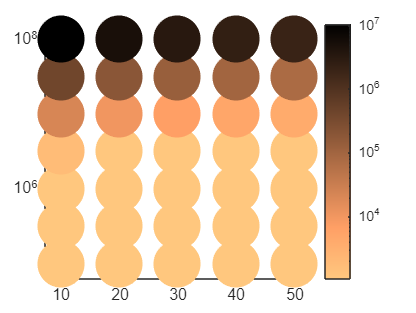

figure
scatter(T_for_plot*1e3, Q_for_plot, 200 + (ratios > 0.045)*600, ratios, 'filled')
set(gca, 'yscale','log', 'colorscale', 'log')
axis('padded')
c = colorbar();
colormap(flipud(copper))

%{
k_B = 1.38065e-23; % m2 kg s-2 K-1
h = 6.62607015e-34; % m2 kg / s

Ts = linspace(0, 5e-3, 20);
ps = zeros(size(Ts));

for j = 1 : length(Ts)
    T = Ts(j);
    Tn = @(f) (0.5*h*f + h*f/(exp(h*f/k_B/T)-1))/k_B;
    ps(j) = Tn(f_a*2);
end

figure
plot(Ts, ps)
yline(h*f_a/k_B/2)
hold on
plot(Ts, Ts)
%set(gca, 'yscale', 'log')
%}

calculate_noise_power(f_sampling, 10e-3)

ans = 1.5843e-17

calculate_noise_power(f_sampling, 20e-3)

ans = 3.2959e-17

k_B * f_sampling/2 * 10e-3

ans = 1.7258e-17

r = @(Q, T) get_ratio(Q, T, f_sampling, noise, f_a, f_a_original, axion_power_over_Q);
r(1e5, 10e-3)

ans = 1.3574

r(1e5, 20e-3)

ans = 0.9411

r(1e5, 30e-3)

ans = 0.7628

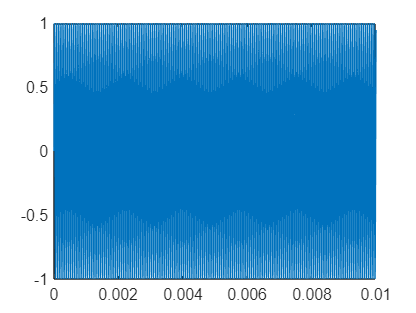

plot(t, sin(95000*t))

bandpower(3*sin(950000*t))

ans = 4.5001

function [ratio, ratio2] = get_ratio(Q, T, f_sampling, noise, f_a, f_a_original, axion_power_over_Q)
    power_sig = axion_power_over_Q * Q;
    band_width = f_a_original / Q;
    noise_power = calculate_noise_power(f_sampling, T);
    noise_ = noise * sqrt(noise_power);
    bandpower(noise_);
    noise_res = resonator_2(noise_, f_a, band_width, f_sampling);
    bandpower(noise_res);

    ratio = sqrt(sqrt(2)) * sqrt(power_sig) / rms(noise_res);

    %bp = bandpower(noise_res)
    %sq = rms(noise_res)^2

    ratio2 = sqrt(2) * power_sig / bandpower(noise_res);
end